# Binarització II

## Labeling

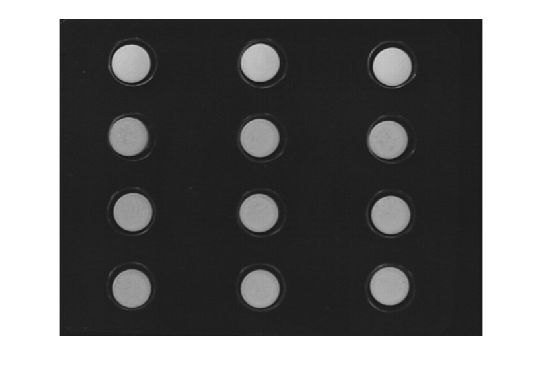

I = rgb2gray(imread('Blispac2.tif'));
imshow(I);

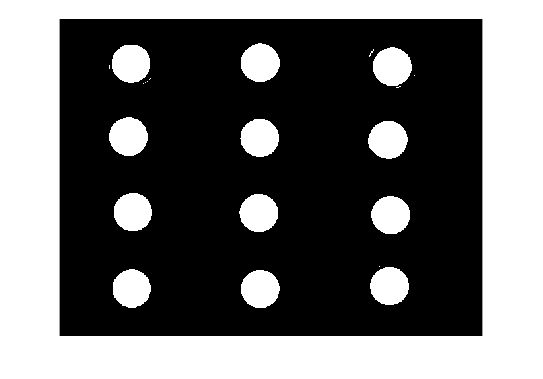

BW = imbinarize(I);
imshow(BW);

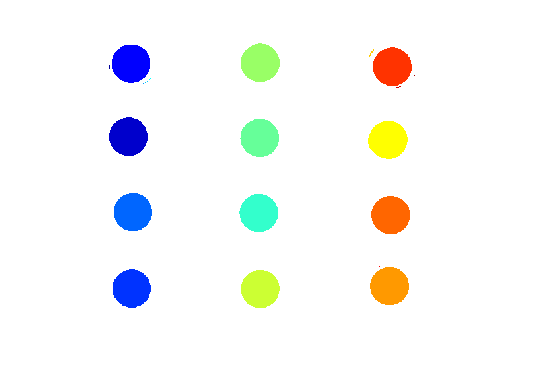

L = bwlabel(BW);
RGB = label2rgb(L);
imshow(RGB);

C = bwconncomp(BW)

C = struct with fields:
    Connectivity: 8
       ImageSize: [480 640]
      NumObjects: 20
    PixelIdxList: {1×20 cell}


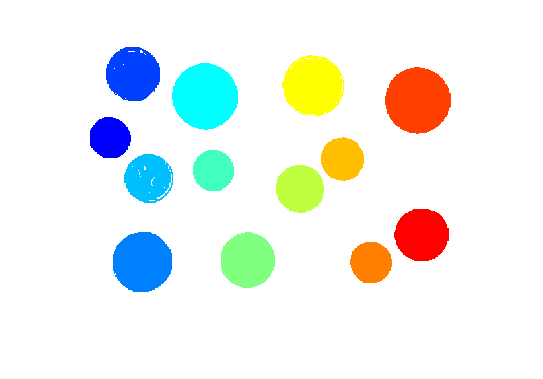

I = imread('money.tif');
t = graythresh(I);
BW = I > 255*t;
L = bwlabel(BW);
RGB = label2rgb(L);
imshow(RGB);

C = bwconncomp(BW)

C = struct with fields:
    Connectivity: 8
       ImageSize: [480 640]
      NumObjects: 13
    PixelIdxList: {[3070×1 double]  [5253×1 double]  [6509×1 double]  [4113×1 double]  [7800×1 double]  [3067×1 double]  [5451×1 double]  [4173×1 double]  [6600×1 double]  [3364×1 double]  [3103×1 double]  [7799×1 double]  [5181×1 double]}


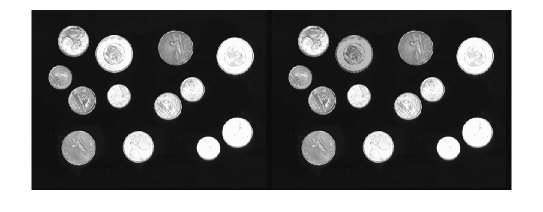

CBW = BW;
IC = I;
IC(C.PixelIdxList{5}) = IC(C.PixelIdxList{5})-64;
montage({I,IC});

## Cerca de la moneda amb més petita (menys píxels)

I = imread('money.tif');
t = graythresh(I);
BW = I > 255*t;
C = bwconncomp(BW)

C = struct with fields:
    Connectivity: 8
       ImageSize: [480 640]
      NumObjects: 13
    PixelIdxList: {[3070×1 double]  [5253×1 double]  [6509×1 double]  [4113×1 double]  [7800×1 double]  [3067×1 double]  [5451×1 double]  [4173×1 double]  [6600×1 double]  [3364×1 double]  [3103×1 double]  [7799×1 double]  [5181×1 double]}


n_pixels = cellfun(@numel,C.PixelIdxList);
[npix, pos] = min(n_pixels);
pos

pos = 6

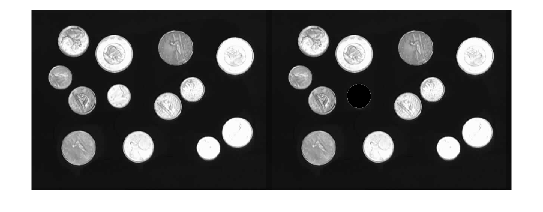

IC = I;
IC(C.PixelIdxList{pos}) = 0;
montage({I,IC});

## Binarització Local

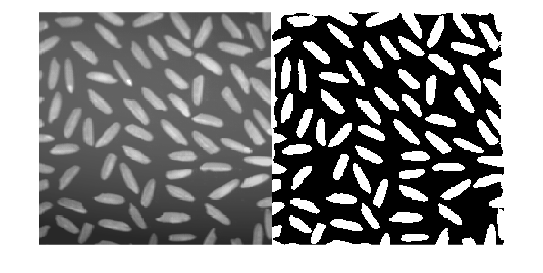

I = imread('arros.tif');
window = [30 30];
M = colfilt(I,window,"sliding",@mean);
BW = I > (M + 16);
montage({I,BW});

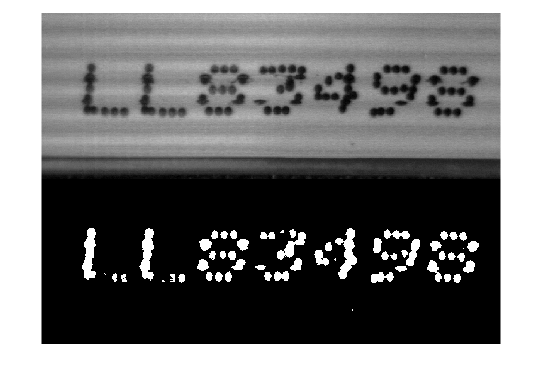

I = imread('FlatCable1.tif');
window = [1 75];
M = colfilt(I,window,"sliding",@mean);
BW = I < (M-25);
montage({I,BW});

## Exercici

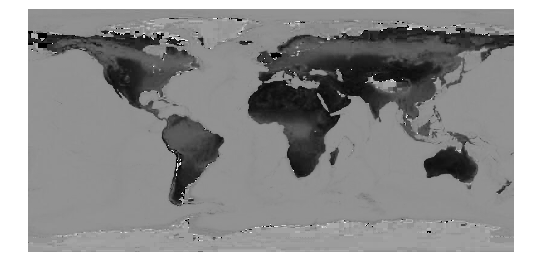

I = imread('mon.jpg');
HSV = rgb2hsv(I);
H = HSV(:,:,1);

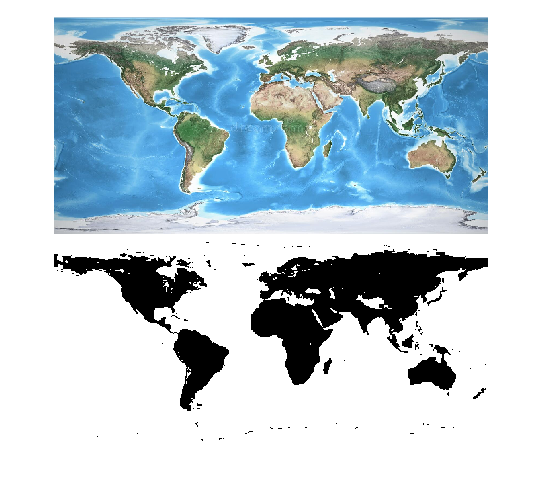

t = graythresh(H);
BW = H > t;
montage({I, BW});